# Изучение красного смещения звезд

close all
clear variables

## Импорт данных

spectra = importdata ("spectra.csv");
starNames = importdata ("star_names.csv");
lambdaStart = importdata ("lambda_start.csv");
lambdaDelta = importdata ("lambda_delta.csv");

## Константы

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/с

## Определение диапазона длин волн и количества звезд

nObs = size (spectra, 1);
nStars = size (starNames, 1);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

## Расчет скорости удаления звезды от Земли

minVectors = zeros (nStars, 2);
for i = 1 : nStars;
    [sHa, idx] = min(spectra (:, i));
    minVectors (i, :) = [sHa, idx];
end

lambdaHa = lambda (minVectors (:, 2));

z = (lambdaHa / lambdaPr) - 1;
speed = z * speedOfLight;

## Определение удаляющихся от Земли звезд

movawayIdx = find (speed > 0);
movaway = starNames (movawayIdx);

## Построение графика

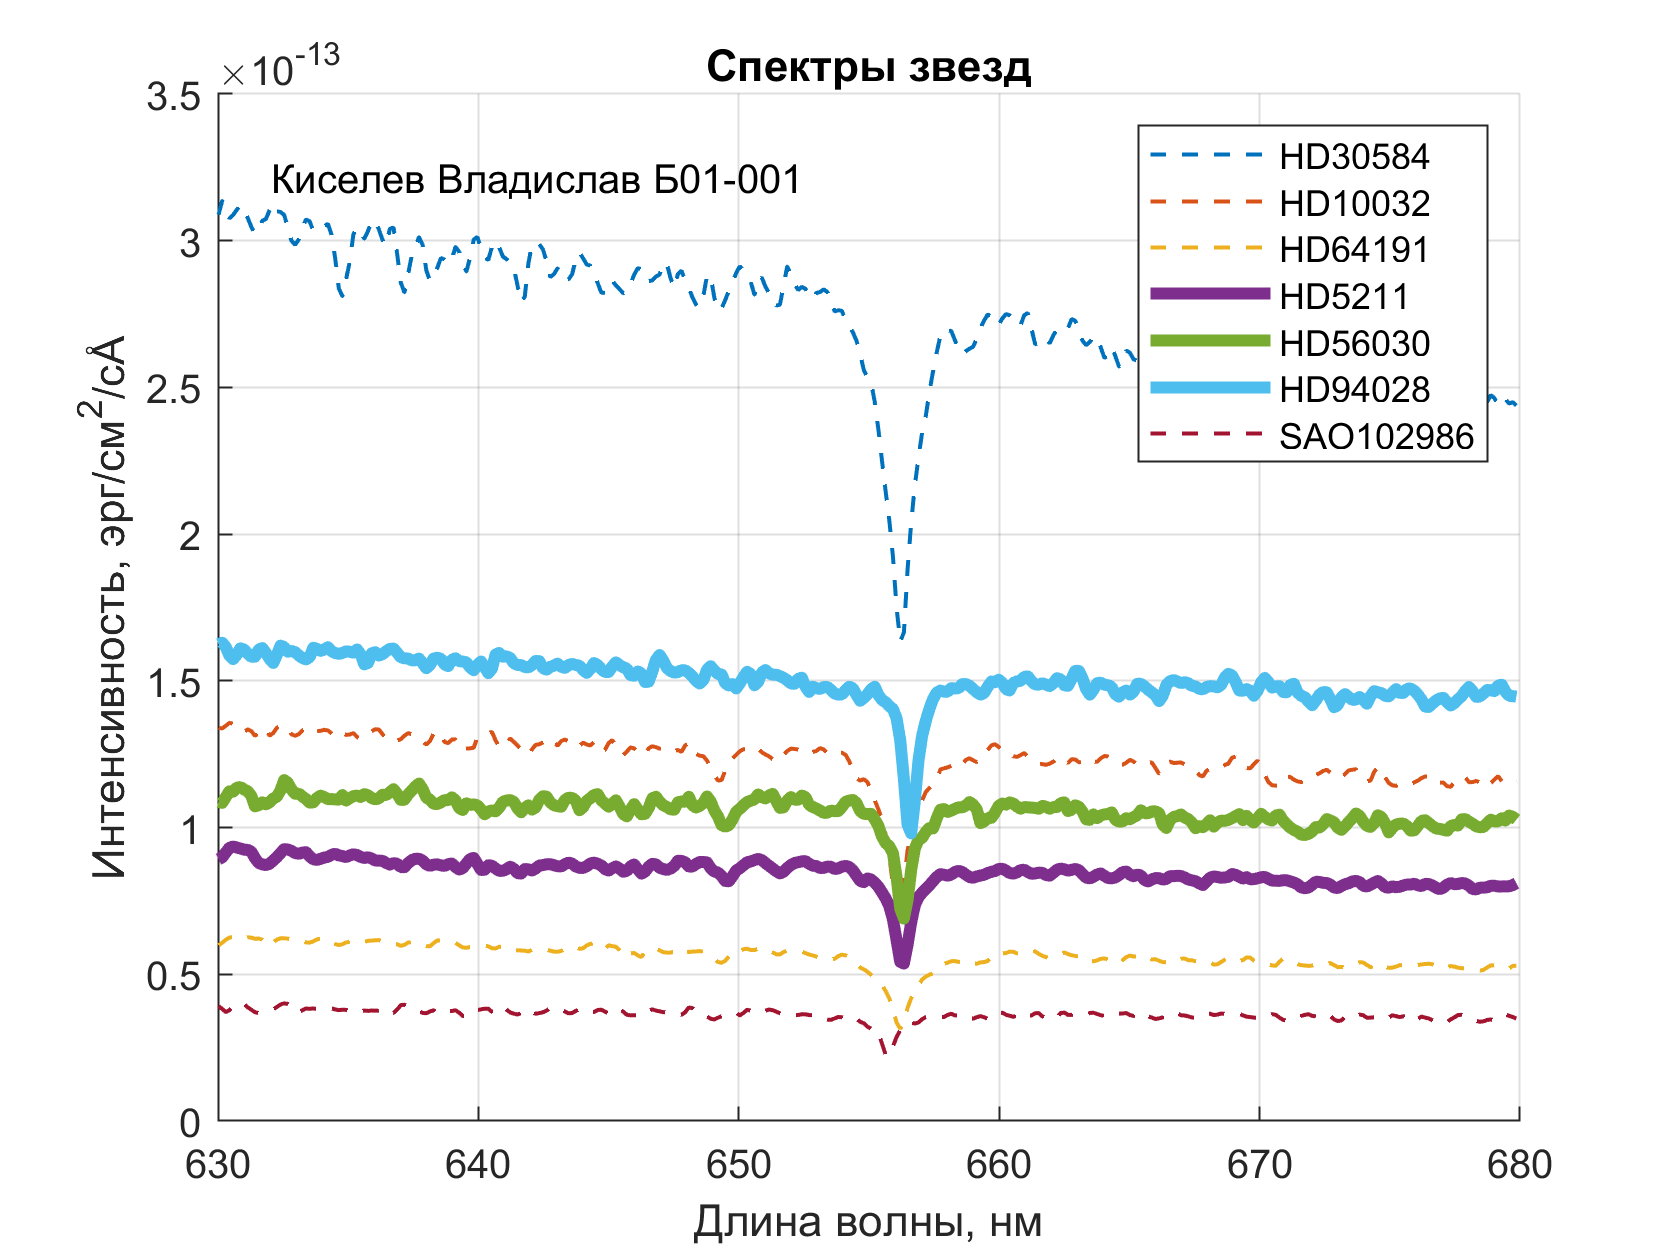

fg1 = figure;
hold on
for i = 1 : nStars 
    s = spectra (:, i);
    if speed (i) < 0 %blue shift
        plot (lambda, s, "--", 'Linewidth', 1);
    else %red shift
        plot (lambda, s, "-", 'Linewidth', 3);
    end    
end
set (fg1, 'Visible', 'on')
xlabel ('Длина волны, нм')
ylabel (['Интенсивность, эрг/см^2/с', char (197)])
title ('Спектры звезд');
legend (starNames, "Location", "northeast")
text(lambdaStart + 2, max (s) * 8, 'Киселев Владислав Б01-001')
grid on
hold off

## Сохранение графика

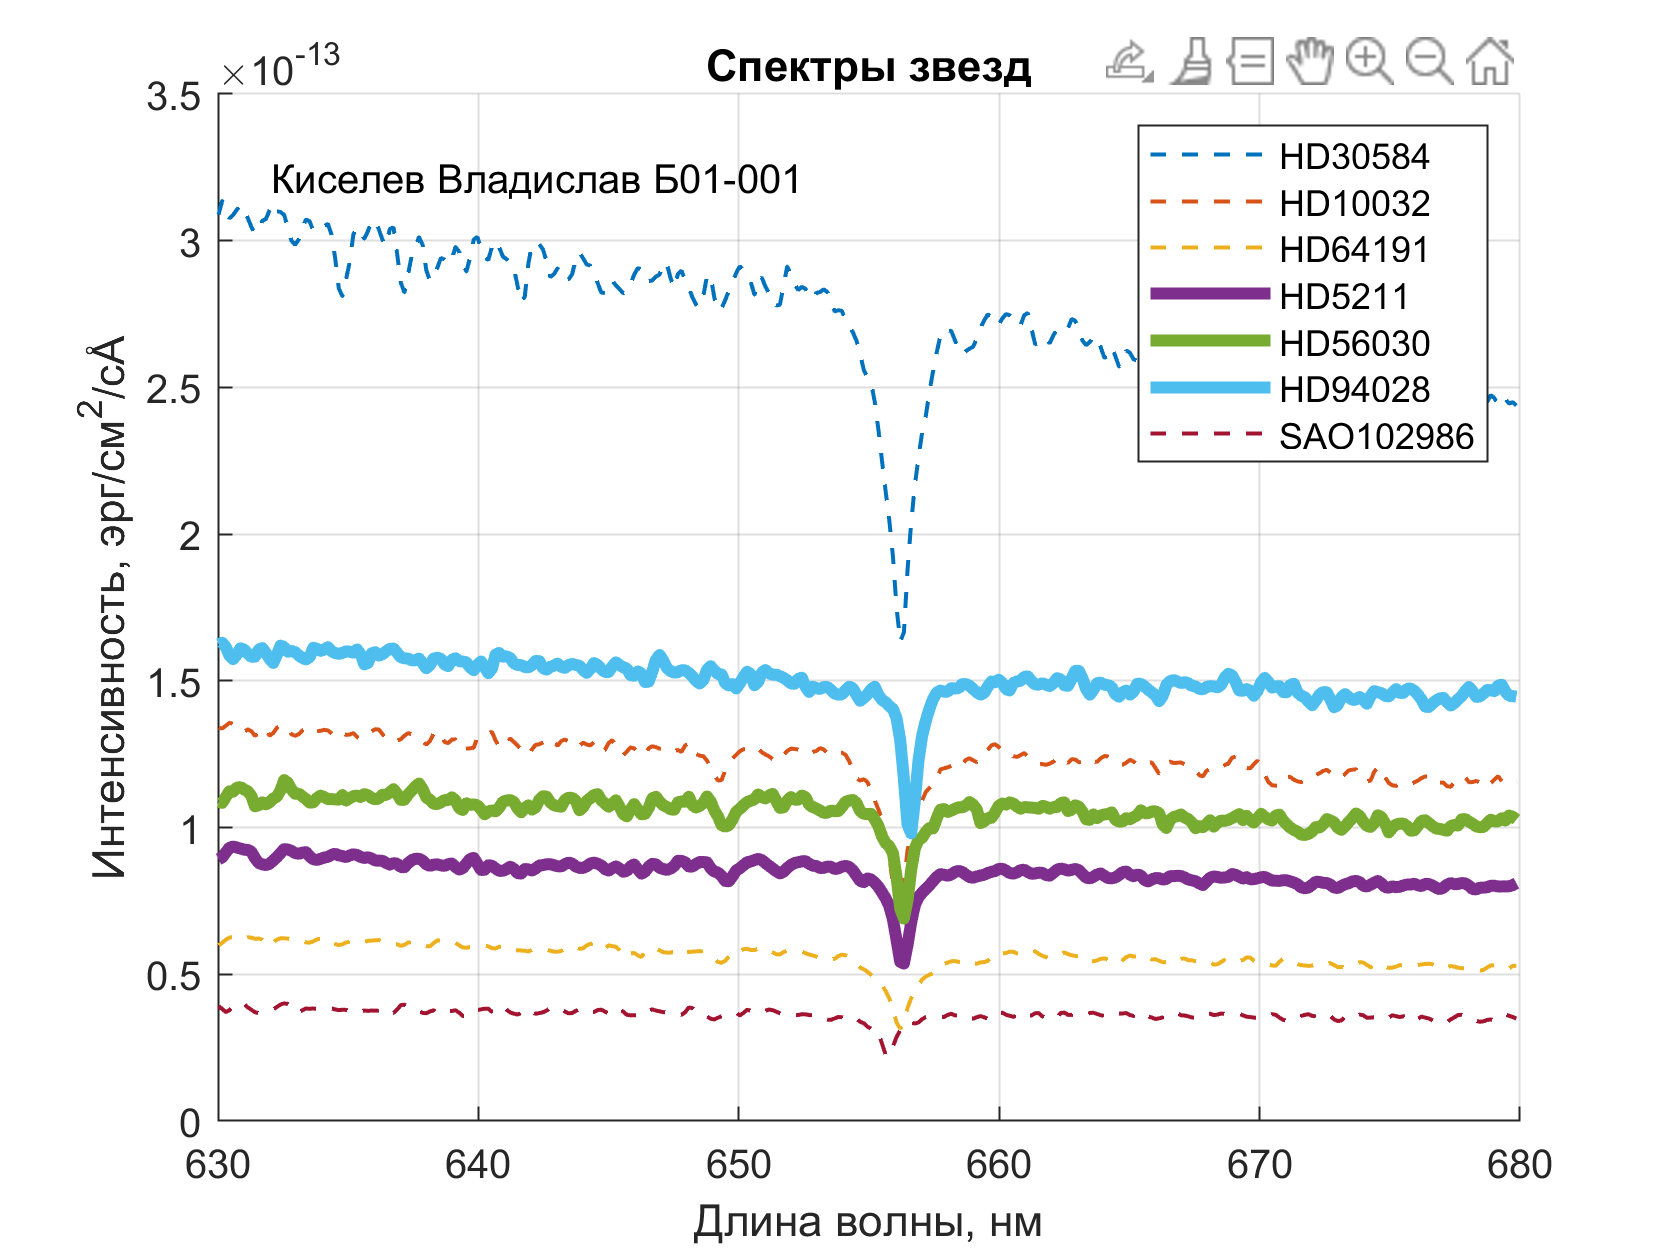

saveas (fg1, 'spectra.png')